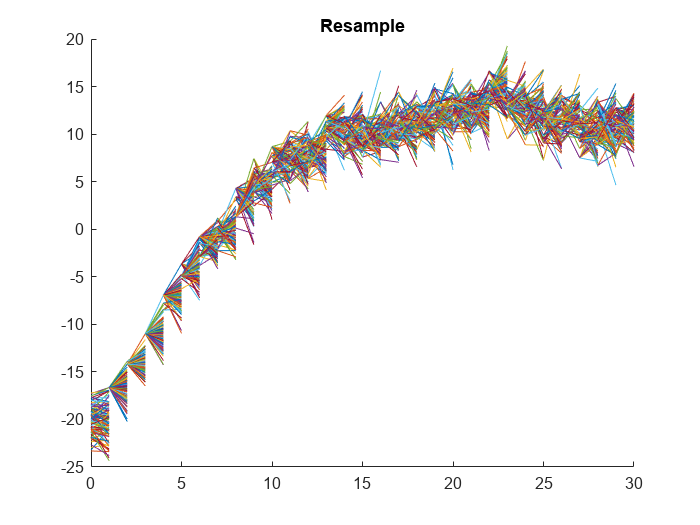

%%Q2
clear;clc;close all;

T = 0.01;

%Model paramters and Matrice
A = 1; H =1;
f = @(x) A*x;
h = @(x) H*x;
Q = 1.5; R = 3;

% Prior for p(x0)
x_0 = -20; P_0 = 2;

% number of time steps
N = 30;

% number of particles
ParticleNum = 100;

% bResample = true;



X = genLinearStateSequence(2, 9, A, Q, N);
Y = genLinearMeasurementSequence(X, H, R);


% [xs, Ps, xf, Pf, xp, Pp] = nonLinRTSsmoother(Y, x_0, P_0, f, T, Q, S, h, R, genSigmaPoints, 'UKF');
% do not have S here


% filter data
[xf, Pf] = kalmanFilter(Y, x_0, P_0, A, Q, H, R);

% function plotPartTrajs(k, Xk, Xkmin1, ~, j)
% Inputs:
%   k           time instance index
%   Xk          [n x N] N particles of dimension n to approximate p(x_k).
%   Xkmin1      [n x N] N particles of dimension n to approximate p(x_k-1).
%   Wk          [1 x N] Corresponding weights.
%   j           Index vector such that Xk(:,i) = Xkmin1(:,j(i))

myplot = @(k, Xk, Xkmin1, j) plotPartTrajs(k, Xk, Xkmin1,[], j);
% pdfplot = @(k, Xk, Wk, xf, Pf, bResample, sigma, ax) plotPostPdf(k, Xk, Wk, xf, Pf, bResample, sigma, ax);

figure;hold on;
[xfpre, Pfpre, Xpre, Wpre] = pfFilter(x_0, P_0, Y, f, Q, h, R, ParticleNum, 1, myplot);
title('Resample')

xlim([0.0 30.0])
ylim([-25.0 20.0])

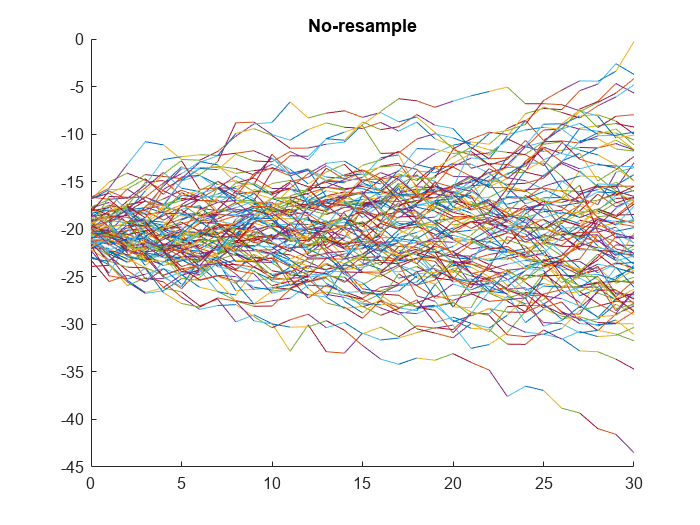

figure;hold on;
[xfp, Pfp, Xp, Wp] = pfFilter(x_0, P_0, Y, f, Q, h, R, ParticleNum, 0, myplot);
title('No-resample')


%xfp is mean and Pfp is covariance
disp('KF mse:')

KF mse:


mse(X(2:end)-xf)

ans = 8.7682

disp('PF with resample')

PF with resample


mse(X(2:end)-xfpre)

ans = 38.7399

disp('PF without resample')

PF without resample


mse(X(2:end)-xfp)

ans = 337.2903

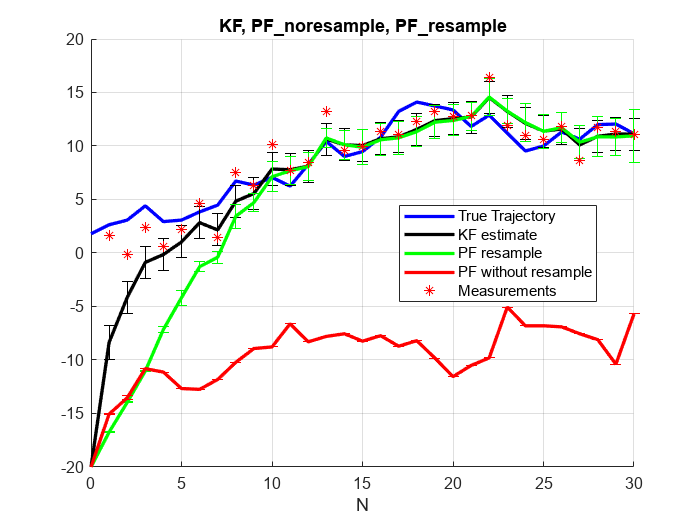



%% plot position
figure;hold on; grid on;
range= 0:1:N;
%True state
p_true = plot(range, X, 'b', 'LineWidth',2, 'DisplayName','True Trajectory');
p_KF = plot(range, [x_0 xf],  'Color','k', 'LineWidth',2, 'DisplayName','KF estimate');
errorbar(1:N,xf,squeeze(Pf(1,1,:))','Color','k','DisplayName','KF cov'); 
p_PFre = plot(range, [x_0 xfpre], 'Color','g', 'LineWidth',2, 'DisplayName','PF resample');
errorbar(1:N,xfpre,squeeze(Pfpre(1,1,:))','Color','g','DisplayName','PF resample cov'); 
p_PF  = plot(range, [x_0 xfp],  'Color','r', 'LineWidth',2, 'DisplayName','PF without resample');
errorbar(1:N,xfp,squeeze(Pfp(1,1,:))','Color','r','DisplayName','PF without resample cov'); 
p_measure = plot(1:N, Y, '*r', 'DisplayName','Measurements');
% p5 = plot(range, H*[x_0 xf] + 3*sqrt([P_0(1) squeeze(Pf(1,1,:))']), '--b', 'DisplayName','+3-sigma level');
% p6 = plot(range, H*[x_0 xf] - 3*sqrt([P_0(1) squeeze(Pf(1,1,:))']), '--b', 'DisplayName','-3-sigma level');
xlabel('N');
legend([p_true p_KF p_PFre p_PF p_measure],'Location','best');
title('KF, PF\_noresample, PF\_resample')

% fp.savefig('q2a-pos')




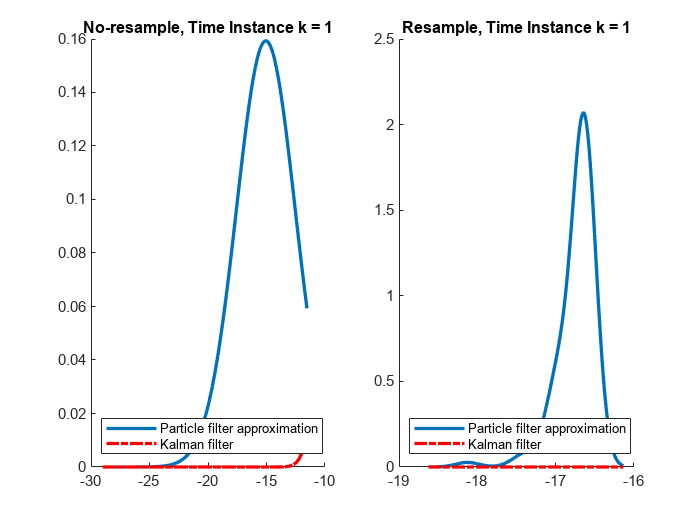

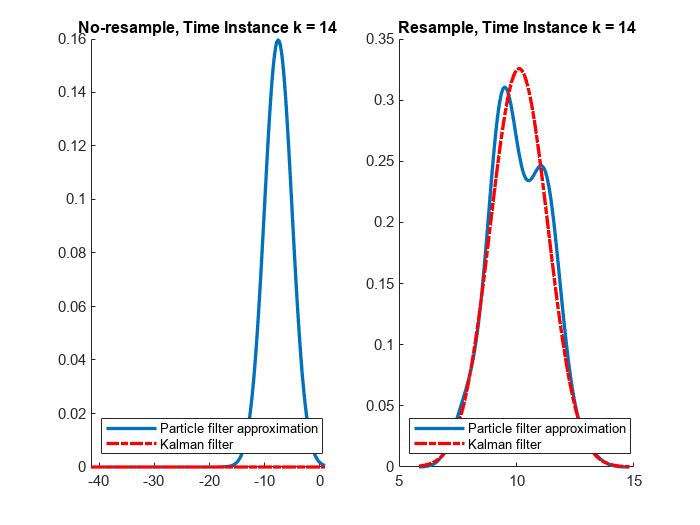

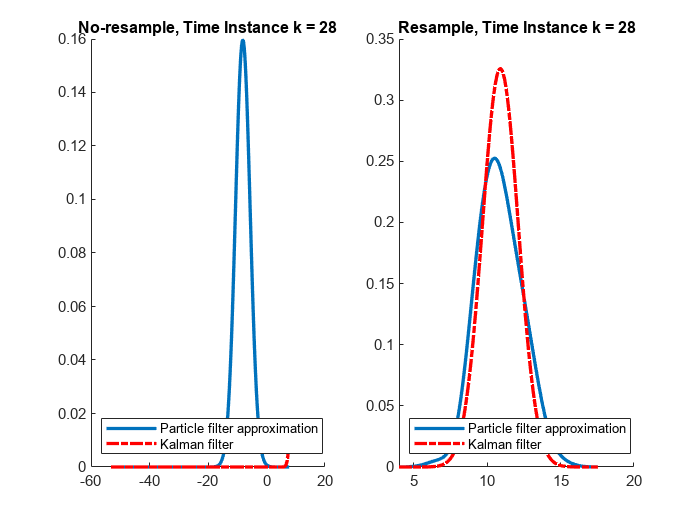

% Define the time instances
% sigma for the approximation in plotPostPdf
sigma = 2.5;
time_instances = [1, 14, 28];
for i= 1:3
    current_k = time_instances(i);

    % Create a new figure
    figure;
    
    subplot(1,2,1);
    hold on;
    % Call pdfplot function for each filte
plotPostPdf(current_k, Xp(:, :, current_k), Wp(:, current_k)', xf, Pf, false, sigma, gca);
    % Set the title and legend
    title(['No-resample, Time Instance k = ' num2str(current_k)]);
    subplot(1,2,2);
    hold on;
plotPostPdf(current_k, Xpre(:, :, current_k), Wpre(:, current_k)', xf, Pf, true, sigma, gca);
    % Set the title and legend
    title(['Resample, Time Instance k = ' num2str(current_k)]);

end